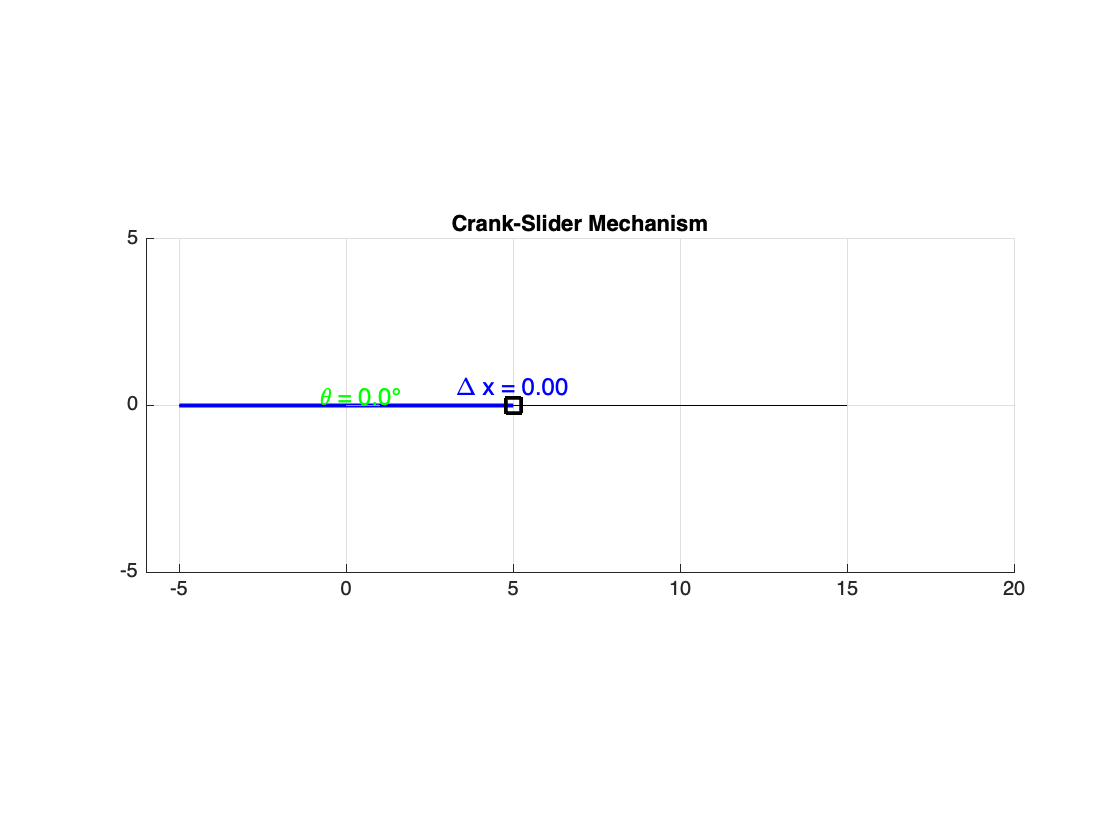

% Crank-Slider Mechanism Simulation with Angle Visualization
clear; clc;

% Parameters
L1 = 5;                      % Crank length
L2 = 10.0;                   % Coupler length
theta_offset = deg2rad(0);   % Crank initial angle offset (deg → rad)

% Generate rotation angles (0° to 180° and back)
theta = linspace(pi, 2*pi, 100);     
theta = [theta, fliplr(theta)];     % Forward and back

% Setup figure
figure;
axis equal;
axis([-6 20 -5 5]);
grid on;
hold on;

% Fixed crank base
A = [0, 0];
r_arc = 1.0;  % Radius of angle arc
initial_Cx = NaN;  % Store initial slider x-position

for i = 1:length(theta)
    cla;
    xlim([-6.0 20.0])
    ylim([-5.0 5.0])

    % Crank angle with offset
    angle = theta(i) + theta_offset;

    % Crank endpoint
    B = A + L1 * [cos(angle), sin(angle)];

    % Slider constrained to y = 0
    discriminant = L2^2 - B(2)^2;
    if discriminant < 0
        continue;
    end
    dx = sqrt(discriminant);
    xC = B(1) + dx;  % Choose rightward root
    C = [xC, 0];

    % Store initial slider position
    if isnan(initial_Cx)
        initial_Cx = C(1);
    end

    % Compute horizontal displacement
    delta_x = C(1) - initial_Cx;

    % Plot crank and coupler
    plot([A(1), B(1)], [A(2), B(2)], 'r-', 'LineWidth', 2); % Crank
    plot([B(1), C(1)], [B(2), C(2)], 'b-', 'LineWidth', 2); % Coupler
    plot(C(1), C(2), 'ks', 'MarkerSize', 10, 'LineWidth', 2); % Slider

    % Display displacement near the slider
    text(C(1), C(2) + 0.5, sprintf('\\Delta x = %.2f', delta_x), ...
         'HorizontalAlignment', 'center', 'FontSize', 12, 'Color', 'b');

    % Ground line
    plot([-5, 15], [0, 0], 'k'); 

    % Reference x-axis line (for angle visualization)
    quiver(A(1), A(2), 1, 0, 0, 'Color', [0.6 0.6 0.6], 'MaxHeadSize', 0.2);

    % Angle between crank and negative x-axis, counterclockwise
    crank_vector = B - A;
    crank_angle = atan2(crank_vector(2), crank_vector(1));  % In radians
    raw_angle = mod(crank_angle - pi, 2*pi);
    display_angle_deg = rad2deg(raw_angle);

    % Draw arc from -x axis to crank
    arc_theta = linspace(pi, pi + raw_angle, 50);
    arc_x = A(1) + r_arc * cos(arc_theta);
    arc_y = A(2) + r_arc * sin(arc_theta);
    plot(arc_x, arc_y, 'g', 'LineWidth', 1.5);

    % Label in center of arc
    text_angle = pi + raw_angle / 2;
    text(A(1) + r_arc * cos(text_angle) + 0.2, ...
         A(2) + r_arc * sin(text_angle) + 0.2, ...
         sprintf('\\theta = %.1f°', display_angle_deg), ...
         'FontSize', 12, 'Color', 'g');

    title('Crank-Slider Mechanism');
    pause(0.01);
end